# Testing SURF algorithm

## Detection of feature points

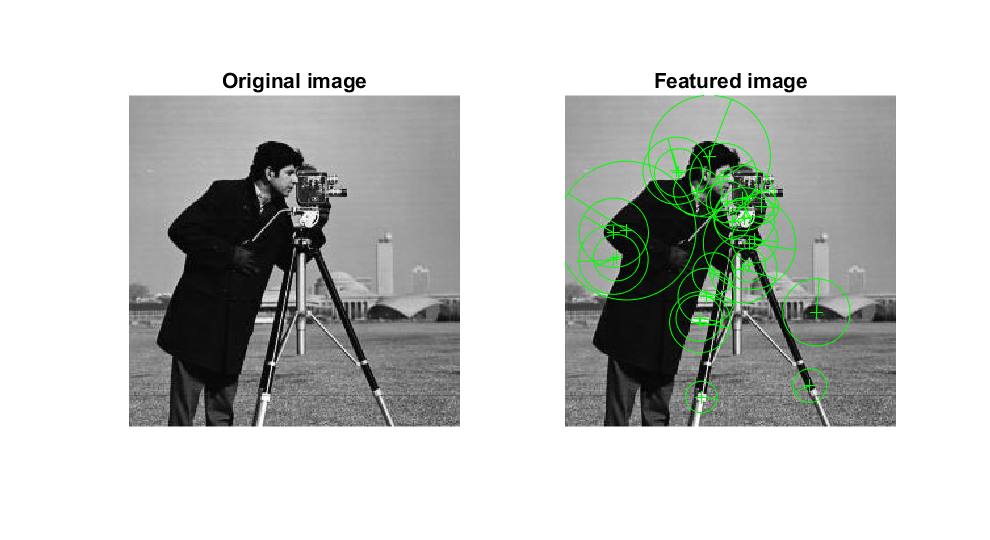

% Read the image
img = imread("./images/test/cameraman_obj.jpg");
img = rgb2gray(img);

% Detect feature points
points = detectSURFFeatures(img);

% Extract the descriptors
[descriptors, points] = extractFeatures(img, points);

% Plot the results
figure('Position', [0, 0, 1800, 1800]);
subplot(121)
imshow(img)
title("Original image")
subplot(122)
imshow(img); hold on;
plot(points.selectStrongest(25), 'ShowOrientation', true);
title("Featured image")
saveas(gcf, "./images/SURF_features.jpg")

## SURF descriptor definition

% Let's study how it is stored in memory the SURF descriptor
descriptors

descriptors = 182×64 single matrix
    0.0011   -0.0023    0.0072    0.0045   -0.0124   -0.0079    0.0371    0.0284    0.0162   -0.0099    0.0215    0.0257    0.0025    0.0007    0.0026    0.0044   -0.0015   -0.0023    0.0190    0.0251    0.1116    0.1342    0.3423    0.2638   -0.0523    0.1515    0.3145    0.2627    0.0047    0.0045    0.0109    0.0285   -0.0048   -0.0044    0.0061    0.0062    0.1693   -0.2304    0.2715    0.3774    0.0113   -0.1680    0.4002    0.2979   -0.0013   -0.0006    0.0015    0.0012   -0.0004    0.0006
    0.0001   -0.0013    0.0013    0.0025   -0.0043    0.0020    0.0463    0.0144    0.0122    0.0027    0.0235    0.0110   -0.0006   -0.0001    0.0020    0.0019   -0.0020    0.0042    0.0117    0.0089    0.1645    0.1716    0.4375    0.1861   -0.1155    0.1760    0.3053    0.2459   -0.0013    0.0010    0.0088    0.0083    0.0015    0.0007    0.0076    0.0148    0.2891   -0.0254    0.4910    0.1770   -0.2462   -0.0756    0.2633    0.1074    0.0015   -0.0001    

Notice for SURF we only use 64-dimensional vectors to describe a point, half of the space we use for SIFT, this makes it faster and it's proved that it's even more robust than SIFT.

The dimensionality of the vector comes from the same point of SIFT, we use a neighbourhood region of 4x4 sub regions and for each subregion we get horizontal and vertical Haar wavelet responses and their sum over over each subregion.

% Example of the first point descriptor vector
descriptors(1, :)

ans = 1×64 single row vector
    0.0011   -0.0023    0.0072    0.0045   -0.0124   -0.0079    0.0371    0.0284    0.0162   -0.0099    0.0215    0.0257    0.0025    0.0007    0.0026    0.0044   -0.0015   -0.0023    0.0190    0.0251    0.1116    0.1342    0.3423    0.2638   -0.0523    0.1515    0.3145    0.2627    0.0047    0.0045    0.0109    0.0285   -0.0048   -0.0044    0.0061    0.0062    0.1693   -0.2304    0.2715    0.3774    0.0113   -0.1680    0.4002    0.2979   -0.0013   -0.0006    0.0015    0.0012   -0.0004    0.0006


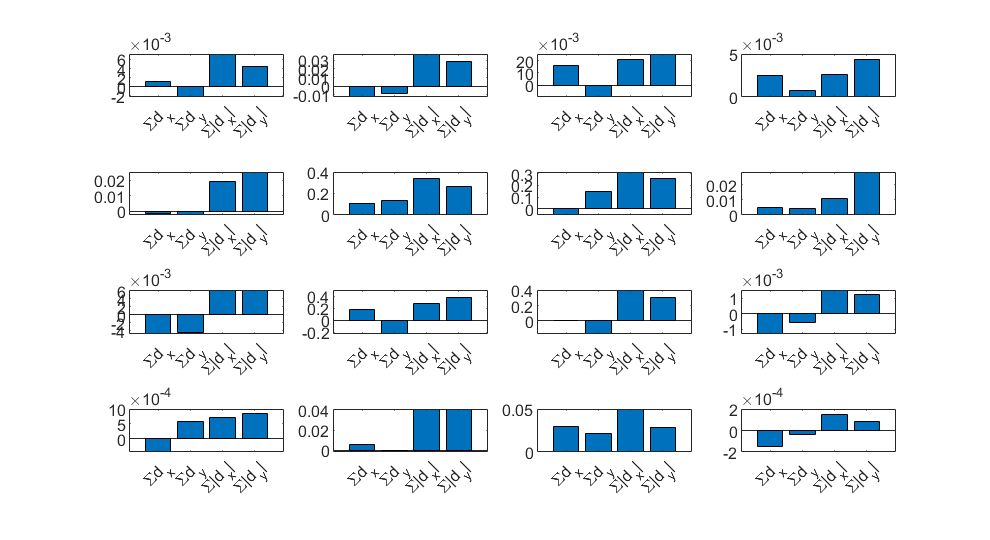

descriptor = descriptors(1, :);  % Take the first descriptor vector
subregions = 16;
x = categorical({'\Sigma{d_x}', '\Sigma{d_y}', '\Sigma{|d_x|}', '\Sigma{|d_y|}'});
figure('Position', [0, 0, 1800, 1800]);
for i=0:subregions-1
    y = descriptor((i*4)+1:(i*4)+4);
    subplot(4,4,i+1);
    bar(x, y);
end
saveas(gcf, "./images/SURF_descriptor.jpg");

## SURF Feature matching

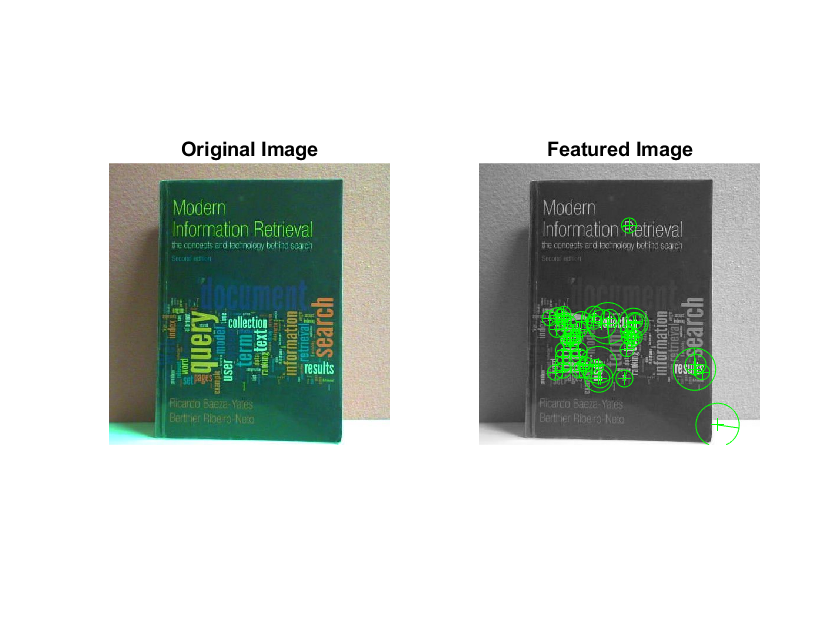

% Read the image of the object
im_obj = imread("./images/test/book_obj.jpg");
obj_gray = rgb2gray(im_obj);

% Detect feature points
fp_obj = detectSURFFeatures(obj_gray);

% Extract the descriptors
[des_obj, fp_obj] = extractFeatures(obj_gray, fp_obj);

% Plot the object image and the featured image
figure;
subplot(121)
imshow(im_obj)
title("Original Image")
subplot(122)
imshow(obj_gray);
hold on;
plot(fp_obj.selectStrongest(50), 'ShowOrientation', true);
hold off
title("Featured Image")
saveas(gcf, "./images/SURF_features_book.jpg")

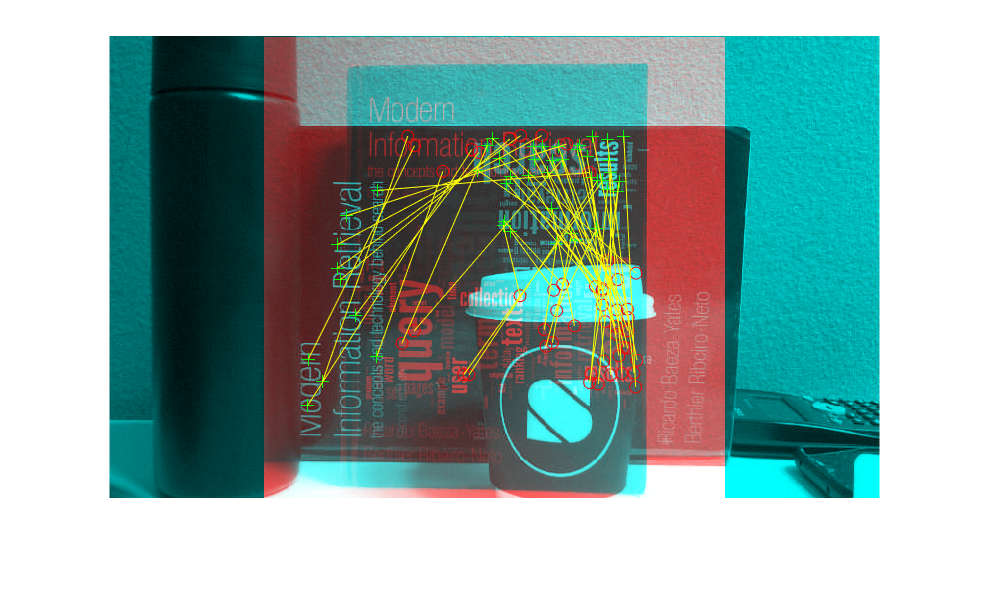

% Match the object features with an image where the object appears
im = imread("./images/test/book.jpg");
im_gray = rgb2gray(im);

% Detect feature points
fp = detectSURFFeatures(im_gray);

% Extract the descriptors
[des, fp] = extractFeatures(im_gray, fp);

[indexPairs,matchmetric] = matchFeatures(des_obj,des);

matchedPoints_obj = fp_obj(indexPairs(:,1),:);
matchedPoints = fp(indexPairs(:,2),:);

figure;
showMatchedFeatures(im_obj,im,matchedPoints_obj,matchedPoints);
saveas(gcf, "./images/matches_book.jpg")